# Optimierung für Industrielogistiker

## Übungsaufgabe 3

Programmieren Sie den die quadratische Anpassung aus dem Skriptum aus. Benützen Sie dafür Ihren 3-Punkt-Muster-Algorithmus aus der Übungsaufgabe 2 und den unten stehenden Code.

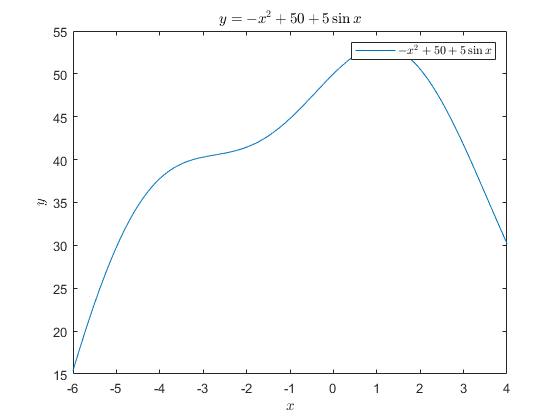

clear variables;
clc;

f = @(x) -x.^2 + 50 + 5 * sin(x);
X_U = -6;
X_O = 4;
x = linspace(X_U, X_O, 1000000);
y = f(x);
plot(x, y);
title('$y = -x^2 + 50 + 5 \sin x$', 'interpreter', 'latex');
xlabel('$x$', 'interpreter', 'latex');
ylabel('$y$', 'interpreter', 'latex');
legend('$-x^2 + 50 + 5 \sin x$', 'interpreter', 'latex');

DELTA = 1;
[xu, xmidpoint, xo] = threepointpatternsearchmethod(f, X_U, DELTA);
MAX_NUMBER_OF_ITERATIONS = 10000000;
EPSILON = 1e-8;
x = quadraticadaptation(f, xu, xmidpoint, xo, EPSILON, DELTA, MAX_NUMBER_OF_ITERATIONS);
disp(['x = ', num2str(x, '%.8f')]);

x = NaN


function [x] = quadraticadaptation(f, xu, xmidpoint, xo, EPSILON, DELTA, MAX_NUMBER_OF_ITERATIONS)
    x = 0; %This line is here to make the code runnable and should not be included the final code.
    
    %your code    
    addpath("HelperFunctions\");  
    
    [x] = myQuadraticAdjustment(f, xu, xmidpoint, xo, EPSILON, DELTA, MAX_NUMBER_OF_ITERATIONS, true);
end

function [xu, xmidpoint, xo] = threepointpatternsearchmethod(f, xu, delta)
    %xmidpoint = xu; %This line is here to make the code runnable and should not be included the final code.
    %xo = xu; %This line is here to make the code runnable and should not be included the final code.
    
    %your code
    addpath("HelperFunctions\");
    
    [xu, xmidpoint, xo] = myThreepointpatternsearchmethod(f, xu, delta, true);    
end